# HW 2 - Matlab Exercise 2

Module 2 consists of 8 sections. loading data as we did before is where we begin

pwd
data = load('../HMP_Dataset/Climb_stairs/Accelerometer-2011-03-24-10-24-39-climb_stairs-f1.txt')
% loading in the data from the csv matrix
data = convert(data)
x = data(:,1);
y = data(:,2);
z = data(:,3);

## Combining of signal

can be done with an anon function

S = @(a, b, c) (sqrt(a.^2 + b.^2 + c.^2 ))

with this we can convert the signal for computing the energy of it.


$$E=\int_{-\infty }^{\infty } |S|^2 \textrm{dt}$$


We are in a discrete environment, so we need the following.


$$E=\sum_{-\infty }^{\infty } |S|^2$$


matlabs sum function can do this across the vector and we can pass in the squared magnitude

E = sum(mag_sigquared)

## 2 combine and calculate energy

sig_sig = S(x, y, z)'
mag_sigquared = abs(sig_sig).^2 
energy_sig = sum(mag_sigquared,"all","omitmissing","double")

The energy of S is obtained.

## 3 Implementation of moving average

showing the moving average working on the data below

avg_vec = [1 1 1]./3
conv_sig = conv(x,avg_vec)
plot(1:1:length(x),x,'b',1:1:length(conv_sig),conv_sig,'r')
title('combined signal and moving avg')
xlabel('samples n')
ylabel('value')
grid on
legend('original','avg')

## Here is the convolved impulse across the signals

hx = filter(avg_vec,1,x);
hy = filter(avg_vec,1,y);
hz = filter(avg_vec,1,z);
convX = conv(hx,x);
convY = conv(hy,y);
convZ = conv(hz,z);
reg_range = (1:1:length(hx))';
new_range = -floor(length(convX)/2):1:floor(length(convX)/2);
figure()
plot(new_range,convX,new_range,-convY,new_range,convZ)
grid on
figure()
plot(reg_range,hx,'k*',1:1:length(x),x,'b:',1:1:length(conv_sig),conv_sig,'r')
title('Original signal with average and filter function')
legend("h_x","x","My_{avg}")
grid on


figure
test = conv(x,x);
plot(1:1:length(test),test)


n = 10

n = 10

t = .1:.01:n*pi

t =     0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900    0.3000    0.3100    0.3200    0.3300    0.3400    0.3500    0.3600    0.3700    0.3800    0.3900    0.4000    0.4100    0.4200    0.4300    0.4400    0.4500    0.4600    0.4700    0.4800    0.4900    0.5000    0.5100    0.5200    0.5300    0.5400    0.5500    0.5600    0.5700    0.5800    0.5900


a = cos(t)

a =     0.9950    0.9940    0.9928    0.9916    0.9902    0.9888    0.9872    0.9856    0.9838    0.9820    0.9801    0.9780    0.9759    0.9737    0.9713    0.9689    0.9664    0.9638    0.9611    0.9582    0.9553    0.9523    0.9492    0.9460    0.9428    0.9394    0.9359    0.9323    0.9287    0.9249    0.9211    0.9171    0.9131    0.9090    0.9048    0.9004    0.8961    0.8916    0.8870    0.8823    0.8776    0.8727    0.8678    0.8628    0.8577    0.8525    0.8473    0.8419    0.8365    0.8309


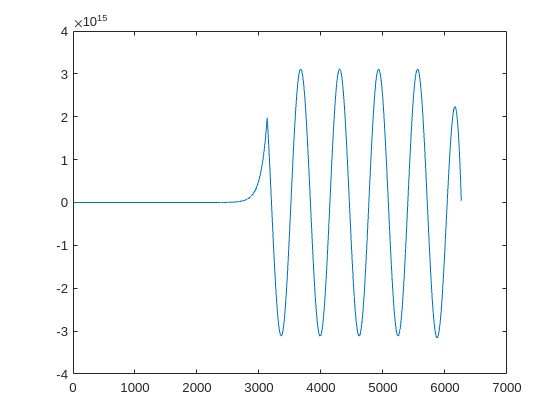

plot(conv(exp(t),a))

function a = convert(data)
g = 9.8; % as in m/s^2
a = -1.5*g + 3*g*(data/63);
end